% PLAN this time: 
% get group cell arrays made first ina  seperate loop
% then, for each point
% get the crf for the 1st session, 
% plot, hold on
% get crf for 2nd session, plot, hold on, etc
% do for each point, one point at a time

% so -
% points loop
% session loop
% contrast loop
% end contrast
% plot crf for that session
% go to next session, same point,
% end sessions
% go to next point, new session, crf


% clear all variables from previous analysis
clear all


% legend info
reigons = {'V1','LM','AL','AM','control'};
cons4Axes = {'0','3','6','12','25','50','100'};
durs4Axes = {'16','33','66','133','266'};
cons4Legend = {'0','0.03','0.063','0.125','0.25','0.5','1'};
durs4Legend = {'16 ms','33 ms','66 ms','133 ms','266 ms'};

% consThreshless4Axes = {'0','0.01','0.02','0.03'};
% dursThreshless4Axes = {'16'};
% consThreshless4Legend = {'0%','1%','2%','3%'};
% dursThreshless4Legend = {'16ms'};


% at this point, vars 4 indivisual & group analysis have already been created

% have matlab ask me how many mice I wanna average over for the present group
clear nGroup
nGroup = input('how many sessions in this group?')

nGroup =      2



% put that number into a for loop, have me get the var mat files that many of times

clear nthVarsFilePaths
clear n
for n = 1:nGroup
    
    [f p] = uigetfile('*.mat',sprintf('session # %0.00f vars4IndAndGroupAnalyses',n));
    
    % make cell array w/ sessions for columns
    % & file names/paths for values down the rows
    
    nthVarsFilePaths{1,n} = f;
    nthVarsFilePaths{2,n} = p;
    
    % load the nth var mat file
    load(fullfile(p,f));
    
    % put each var (could be a struct, matrix, etc) into a column of a cell array: 
    % all will be % 1 x # sessions
    groupStimDetails{1,n} = stimDetails; % 1 x # sessions
    groupSubjData{1,n} = subjData; % 1 x # sessions
    groupTrialCond{1,n} = trialCond;
    groupNumPreStimFrames{1,n} = numPreStimFrames;
    groupNumPostStimFrames{1,n} = numPostStimFrames;
    groupIdxOnsetsMeetBothCriteria{1,n} = idxOnsetsMeetBothCriteria;
    groupPeakFrameIdx{1,n} = peakFrameIdx;
    groupBaselineIdx{1,n} = baselineIdx;
    groupMeanActImFrames{1,n} = meanActImFrames;
    groupRoundXpts{1,n} = RoundXpts;
    groupRoundYpts{1,n} = RoundYpts;
    groupPTSdfof{1,n} = PTSdfof;
    
end % now I have the group analysis vars for each session


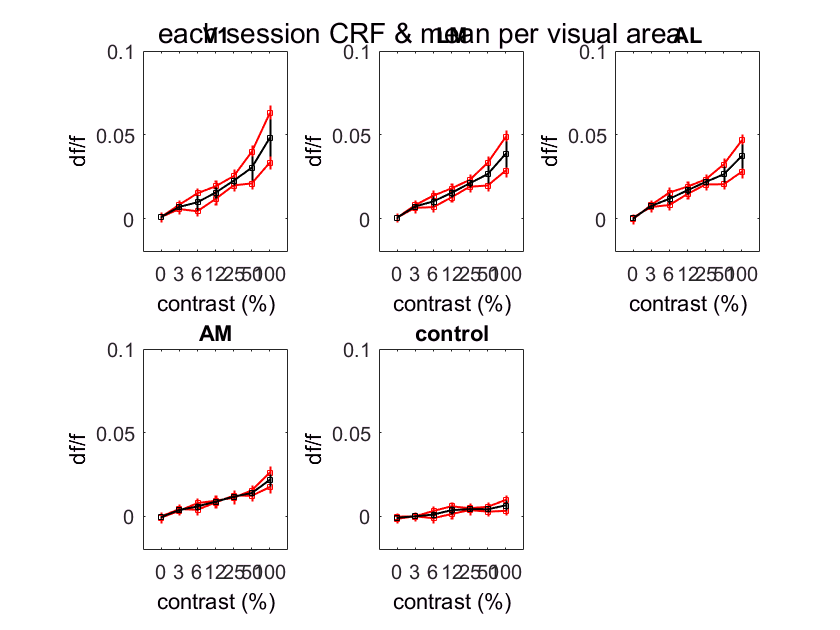

% CRF for each session at each point

% figs need to be at top so don't make new one for each point or session
% figure % one fig, mean & session CRFss per area
% suptitle('each session CRF & mean per visual area')
figure % one fig, mean & session CRFss per area
suptitle('each session CRF & mean per visual area')

clear i 
for i = 1:length(RoundXpts) % for each point, calulate the crf
    
    clear n
    for n = 1:nGroup % for each session/mouse
        
        % CON & DUR VALUES AT EACH TRIAL - these values get calculated anew for each session 
    
        % EXTRACT VARS from GROUP CELL ARRAYS
        % save variable for nth sessions stim details struct array
        nthStimDetailsStruct = groupStimDetails{n};
        % now we can use that struct array exatly as we usually would use stimDetails in the individual analysis
        % save variable for trial cond, which is stored as double inside an array
        nthTrialCond = groupTrialCond{1,n}; % nthTrialCond is a double
        nthIdxOnsetsMeetBothCriteria = groupIdxOnsetsMeetBothCriteria{1,n}; % this var is a double


        % CONTRAST calc's
        clear con
        clear conOrderedByTrial  
        clear conOrderedByTrialMeetCriteria 
        clear uniqueContrasts

        clear c % % still in session loop, for each stim condition, get contrast value, store all in vector
        for c = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
            con(c) = nthStimDetailsStruct(c).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
        end

        conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
        conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetBothCriteria);
        uniqueContrasts = unique(con); % for looping over contrast values later

        %%  DURATION Calc's
        clear dur
        clear durOrderedByTrial  
        clear durOrderedByTrialMeetCriteria 
        clear uniqueDurations

        % extract duration field from stimDetails
        clear d
        for d = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
            dur(d) = nthStimDetailsStruct(d).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
        end

        durOrderedByTrial = dur(nthTrialCond); 
        durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetBothCriteria);
        uniqueDurations = unique(dur);

        %% CON & DUR TOGETHER
        clear conAndDur 
        clear conAndDurOrderedByTrial 
        clear conAndDurOrderedByTrialMeetCriteria

        % putting together dur & con so that I can index into the trials in order w/trialCond
        conAndDur = [con; dur];
        % put it in order of trial presentation:
        conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
        conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetBothCriteria(1,n));
        
        % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
        % extract nth PTSdfof
        nthPTSdfof = groupPTSdfof{1,n};
        % save variable for for nth peakFrameIndex
        nthPeakFrameIdx = groupPeakFrameIdx{1,n}; 
        % save variable for for nth baseline frames
        nthBaselineIdx = groupBaselineIdx{1,n};
    
        % get CRF for nth session & ith point
        clear CRFminusMeanBase 
        clear c
        for c = 1:length(uniqueContrasts) % for each contrast, calulate the mean response at the ith point
                
            % select the right TRIALS
            clear cthTrials
            cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c); 
        
            % calculate CRF for that session/mouse
            % take the i-th points over the frame range, for the c-th trials
            % returns 3 (frames) by # trials
            clear sq5FramesOverTrialsPTSdfof
            sq5FramesOverTrialsPTSdfof = squeeze(nthPTSdfof(i,nthPeakFrameIdx,cthTrials));
            % take the mean over frames, returns 1 x # trials
            clear meanOverFramesSq5FramesOverTrialsPTSdfof
            meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
            % now I need the mean over trials to get one df/f value representing the
            % average fluorescence over 3 frames and over the c-th trials for the i-th point
            meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
            % collect each c-th CRF value for this point
            crf(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
            % GET mean BASEline for nth session/mouse
            % the baseline for each CRF value is the mean of the baseline frames for
            % the ith point and cth contrast
            % get all frames & cth trials
            clear baselineFramesIthPtCthTrials
            baselineFramesIthPtCthTrials = squeeze((nthPTSdfof(i,nthBaselineIdx,cthTrials)));
            % now have baseline frames x trials
            % take mean across trials 
            clear  meanBaselineFramesIthPtCthTrial
            meanBaselineFramesIthPtCthTrials = mean(baselineFramesIthPtCthTrials,2);
            % take mean across frames
            meanBaselineFramesIthPtCthTrials = mean(meanBaselineFramesIthPtCthTrials,1);
            
            % do BASEline CORRECTION
            % subtract the cth baseline from the flourescence at each c
            CRFminusMeanBase(c) = crf(c)-meanBaselineFramesIthPtCthTrials; % clear this var in between subplots
        
            % not sure what stderr I'm going to end up using for group
            % but let's save these out too just in case
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
            conStdErr(1,c) = stdErr; % clear outside i loop
            
        end % end contrast loop, now you have CRF for one point, one session. plot on
        % subplot for ith point, hold on, do the contrast loop for the next session, plot on same subplot

        % PLOTting nth CRF for ith point & nth session 
        subplot(2,3,i) % one subplot each visual area
        x_axis = 1:length(uniqueContrasts);
        errorbar(x_axis,CRFminusMeanBase,conStdErr,'-rs','MarkerSize',3,'linewidth',1); 
%       errorbar(x_axis,CRFminusMeanBase,conStdErr,'-s','MarkerSize',3,...
%       'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
        title(reigons{i})
  
        ylim([-0.02 0.1]) 
        xlim([0, 8])
        set(gca,'xtick',1:length(uniqueContrasts)); 
        set(gca,'xticklabel',cons4Axes);
        ylabel('df/f')
        xlabel('contrast (%)')
        
        hold on % still w/in the sessions loop, which is in the points loop
        % my subplot value (point/visual area) has not advanced
        % my session has not yet advanced
        
        % BEFORE you END the PTS LOOP & before your SESSION loop variable advances
        % save the CRF values for the ith point & nth session
        
%         % I guess I'll save out the stderr for each crf? why not...
%         % PTS x STDERR x SESSION matrix
%         allSessAllPtsConStdErr(i,:,n) = conStdErr;

        % SAVE the resulting vector in a ** GROUP MATRIX **
        % note: since I'm going thru this one session at a time, I can't index from this matrix
        % until the end when I have all sessions in it... but, that's not aproblem 
        % because I can plot CRF's one by one (for the overlay) and then at the end I think I can
        % take the mean... so store this vector here, but don' use it until plotting the mean
        % POINTS x CRF x SESSION matrix
        allSessAllPtsCRFminusMeanBase(i,:,n) = CRFminusMeanBase;
 
   end % end n/sessions loop once all session's CRF's plotted for each point, move onto the next point where you once again go ingot a sessions loop and plot the, crf for each session for the next point/subplot

end % end points loop, as now crf's for each session and all points are plotted

hold on % will this let me hold onto the entire fig or no?

% PLOTTting MEAN
clear i 
for i = 1:length(RoundXpts) % for each point, plot the mean crf across sessions

    % don't need to calulate CRF this time becuase i saved them all out in above code
     ithAllSessCRFallSessAllPts = allSessAllPtsCRFminusMeanBase(i,:,:); % one point, all contrasts, all sessions,  
     ithAllSessCRFallSessAllPts = squeeze(ithAllSessCRFallSessAllPts); % getting the dimensions better for taking means
     ithAllSessCRFallSessAllPts = ithAllSessCRFallSessAllPts';
     ithMeanCRFAcrossSess = mean(ithAllSessCRFallSessAllPts,1);  % the mean CRF across sessions for the ith point

    % I think this is how to calulate group STDERR?:
    groupStdErr = std(ithAllSessCRFallSessAllPts,1)/(sqrt(nGroup));

    % PLOTting nth CRF for ith point & nth session 
    subplot(2,3,i) % one subplot each visual area
    x_axis = 1:length(uniqueContrasts);
    errorbar(x_axis,ithMeanCRFAcrossSess,groupStdErr,'-ks','MarkerSize',3,'linewidth',1); 
    title(reigons{i})
  
    ylim([-0.02 0.1]) 
    xlim([0, 8])
    set(gca,'xtick',1:length(uniqueContrasts)); 
    set(gca,'xticklabel',cons4Axes);
    ylabel('df/f')
    xlabel('contrast (%)')

end % end points loop


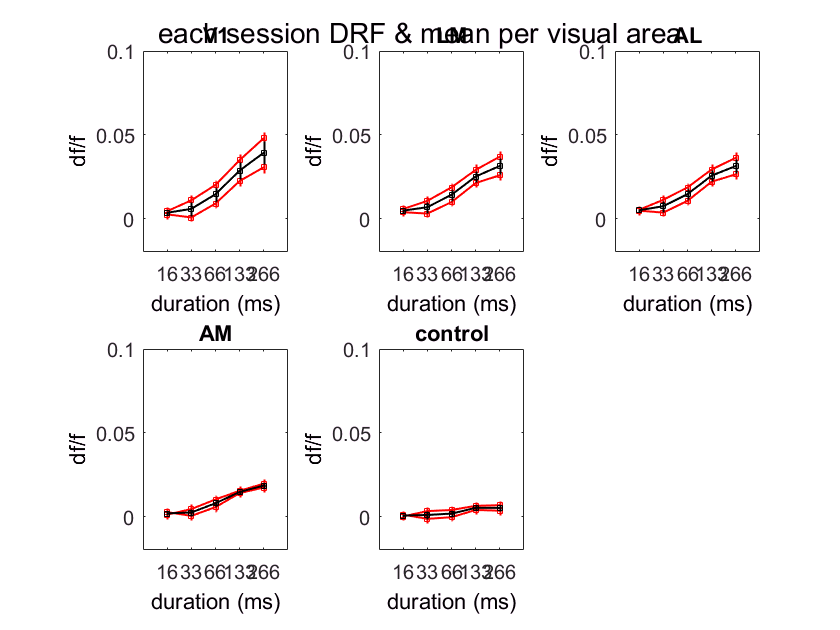

% now let's do the exact same thing but for duration response curve

% DRF for each session at each point

% figs need to be at top so don't make new one for each point or session
% figure % one fig, mean & session CRFss per area
% suptitle('each session CRF & mean per visual area')
figure % one fig, mean & session CRFss per area
suptitle('each session DRF & mean per visual area')

clear i 
for i = 1:length(RoundXpts) % for each point, calulate the crf
    
    clear n
    for n = 1:nGroup % for each session/mouse
        
        % CON & DUR VALUES AT EACH TRIAL - these values get calculated anew for each session 
    
    % extract nth PTSdfof
    % EXTRACT VARS from GROUP CELL ARRAYS
    % save variable for nth sessions stim details struct array
    nthStimDetailsStruct = groupStimDetails{n};
    % now we can use that struct array exatly as we usually would use stimDetails
    % in the individual analysis
    % save variable for trial cond, which is stored as double inside an array
    nthTrialCond = groupTrialCond{1,n}; % nthTrialCond is a double
    nthIdxOnsetsMeetBothCriteria = groupIdxOnsetsMeetBothCriteria{1,n}; % this var is a double
    % extract round points from this session by assigning variable for contents of array cell

    %%  DURATION Calc's

    clear dur
    clear durOrderedByTrial  
    clear durOrderedByTrialMeetCriteria 
    clear uniqueDurations

    % extract duration field from stimDetails
    clear d
    for d = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
        dur(d) = nthStimDetailsStruct(d).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
    end

    durOrderedByTrial = dur(nthTrialCond); 
    durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetBothCriteria);
    uniqueDurations = unique(dur);
        
    % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
        % extract nth PTSdfof
        nthPTSdfof = groupPTSdfof{1,n};
        % save variable for for nth peakFrameIndex
        nthPeakFrameIdx = groupPeakFrameIdx{1,n}; 
        % save variable for for nth baseline frames
        nthBaselineIdx = groupBaselineIdx{1,n};
    
        clear DRFminusMeanBase % get DRF for that session & point
        clear d
        for d = 1:length(uniqueDurations) % for each contrast, calulate the mean response at the ith point
                
            % select the right TRIALS
            clear dthTrials
            dthTrials = durOrderedByTrialMeetCriteria == uniqueDurations(d); 
        
            % calculate DRF for that session/mouse
            % take the i-th points over the frame range, for the c-th trials
            % returns 3 (frames) by # trials
            clear sq5FramesOverTrialsPTSdfof
            sq5FramesOverTrialsPTSdfof = squeeze(nthPTSdfof(i,nthPeakFrameIdx,dthTrials));
            % take the mean over frames, returns 1 x # trials
            clear meanOverFramesSq5FramesOverTrialsPTSdfof
            meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
            % now I need the mean over trials to get one df/f value representing the
            % average fluorescence over 3 frames and over the c-th trials for the i-th point
            meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
            % collect each c-th DRF value for this point
            drf(d) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
            % GET mean BASEline for nth session/mouse
            % the baseline for each DRF value is the mean of the baseline frames for
            % the ith point and cth contrast
            % get all frames & cth trials
            clear baselineFramesIthPtDthTrials
            baselineFramesIthPtDthTrials = squeeze((nthPTSdfof(i,nthBaselineIdx,dthTrials)));
            % now have baseline frames x trials
            % take mean across trials 
            clear  meanBaselineFramesIthPtDthTrial
            meanBaselineFramesIthPtDthTrials = mean(baselineFramesIthPtDthTrials,2);
            % take mean across frames
            meanBaselineFramesIthPtDthTrials = mean(meanBaselineFramesIthPtDthTrials,1);
            
            % do BASEline CORRECTION
            % subtract the cth baseline from the flourescence at each c
            DRFminusMeanBase(d) = drf(d)-meanBaselineFramesIthPtDthTrials; % clear this var in between subplots
        
            % not sure what stderr I'm going to end up using for group
            % but let's save these out too just in case
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(dthTrials)); % sum trials, not length
            durStdErr(1,d) = stdErr; % clear outside i loop
            
        end % end contrast loop, now you have DRF for one point, one session. plot on
        % subplot for ith point, hold on, do the contrast loop for the next session, plot on same subplot

        % PLOTting nth DRF for ith point & nth session 
        subplot(2,3,i) % one subplot each visual area
        clear x_axis
        x_axis = 1:length(uniqueDurations);
         errorbar(x_axis,DRFminusMeanBase,durStdErr,'-rs','MarkerSize',3,'linewidth',1); 
%         errorbar(x_axis,DRFminusMeanBase,conStdErr,'-s','MarkerSize',3,...
%         'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
        title(reigons{i})
  
        ylim([-0.02 0.1]) 
        xlim([0, 6])
        set(gca,'xtick',1:length(uniqueDurations)); 
        set(gca,'xticklabel',durs4Axes);
        ylabel('df/f')
        xlabel('duration (ms)')
        
        hold on % still w/in the sessions loop, which is in the points loop
        % my subplot value (point/visual area) has not advanced
        % my session has not yet advanced
        
        % BEFORE you END the PTS LOOP & before your SESSION loop variable advances
        % save the DRF values for the ith point & nth session
    
        % SAVE the resulting vector in a ** GROUP MATRIX **
        % note: since I'm going thru this one session at a time, I can't index from this matrix
        % until the end when I have all sessions in it... but, that's not aproblem 
        % because I can plot DRF's one by one (for the overlay) and then at the end I think I can
        % take the mean... so store this vector here, but don' use it until plotting the mean
        % POINTS x DRF x SESSION matrix
        allSessAllPtsDRFminusMeanBase(i,:,n) = DRFminusMeanBase;
        
        % I guess I'll save out the stderr for each crf? why not...
        % PTS x STDERR x SESSION matrix
        allSessAllPtsDurStdErr(i,:,n) = durStdErr;
 
   end % end n/sessions loop once all session's DRF's plotted for each point,
   % move onto the next point where you once again go ingot a sessions loop and plot the
   % crf for each session for the next point/subplot

end % end points loop, as now DRF's for each session and all points are plotted

hold on % will this let me hold onto the entire fig or no?

clear i 
for i = 1:length(RoundXpts) % for each point, plot the mean crf across sessions

% don't need to calulate DRF this time becuase i saved them all out in above code

 ithAllSessDRFallSessAllPts = allSessAllPtsDRFminusMeanBase(i,:,:); % one point, all contrasts, all sessions,  
 ithAllSessDRFallSessAllPts = squeeze(ithAllSessDRFallSessAllPts); % getting the dimensions better for taking means
 ithAllSessDRFallSessAllPts = ithAllSessDRFallSessAllPts';
 ithMeanDRFAcrossSess = mean(ithAllSessDRFallSessAllPts,1);  % the mean DRF across sessions for the ith point

% I think this is how to calulate group STDERR?:
groupStdErr = std(ithAllSessDRFallSessAllPts,1)/(sqrt(nGroup));

    % PLOTting nth DRF for ith point & nth session 
        subplot(2,3,i) % one subplot each visual area
        x_axis = 1:length(uniqueDurations);
        errorbar(x_axis,ithMeanDRFAcrossSess,groupStdErr,'-ks','MarkerSize',3,'linewidth',1); 
        title(reigons{i})
  
        ylim([-0.02 0.1]) 
        xlim([0, 6])
        set(gca,'xtick',1:length(uniqueDurations)); 
        set(gca,'xticklabel',durs4Axes);
        ylabel('df/f')
        xlabel('duration (ms)')

end % end points loop

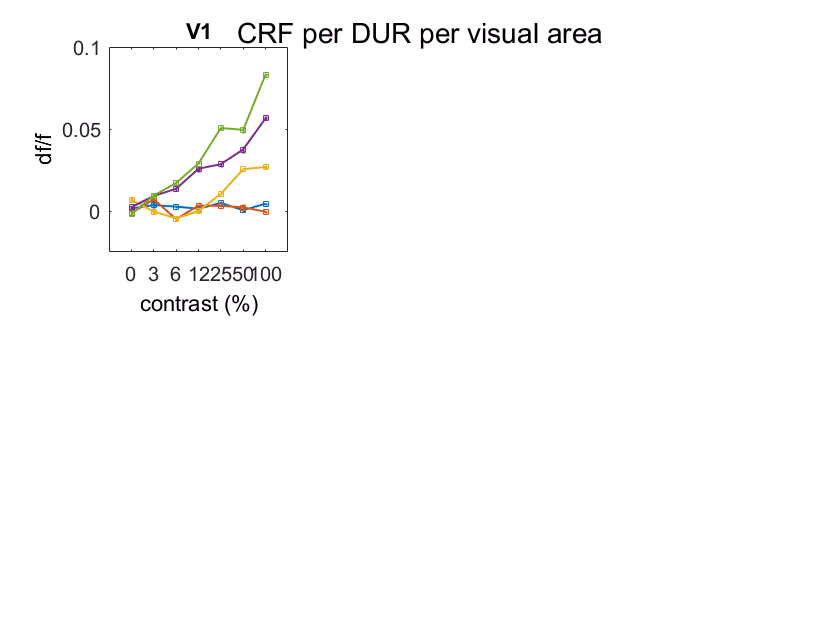

% now, CON & DUR together
% try to cut & paste indivisual con & dur code into this the right way...

% PLAN: don't need to plot on same subplot over and over here since I just need the sessions matric first, so I'll loop in this order:
% for each session
% (load vars)
% for each point
% for each duration
% calculate CRF
% save in matrix for points, duration, crf, session
% do for all durations at that point
% move onto the next point, repeat dth CRF calulations until all are done for that session
% move onto next session etx until sessions matrix is filled
 
% for each SESSION
clear allSessAllPtsAllDurCRFminusMeanBase % clearing group matrix just in case not running script from top (clear all)
clear n 
for n = 1:nGroup % for each session/mouse
        
    % CON & DUR VALUES AT EACH TRIAL - these values get calculated anew for each session 
    % EXTRACT VARS from GROUP CELL ARRAYS
    nthStimDetailsStruct = groupStimDetails{n};
    nthIdxOnsetsMeetBothCriteria = groupIdxOnsetsMeetBothCriteria{1,n}; % this var is a double
    % CONTRAST calc's
    clear con
    clear conOrderedByTrial  
    clear conOrderedByTrialMeetCriteria 
    clear uniqueContrasts
    clear c % % still in session loop, for each stim condition, get contrast value, store all in vector
    for c = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
        con(c) = nthStimDetailsStruct(c).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
    end
    conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
    conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetBothCriteria);
    uniqueContrasts = unique(con); % for looping over contrast values later
    %%  DURATION Calc's
    clear dur
    clear durOrderedByTrial  
    clear durOrderedByTrialMeetCriteria 
    clear uniqueDurations
    % extract duration field from stimDetails
    clear d
    for d = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
        dur(d) = nthStimDetailsStruct(d).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
    end
    durOrderedByTrial = dur(nthTrialCond); 
    durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetBothCriteria);
    uniqueDurations = unique(dur);
    %% CON & DUR TOGETHER
    clear conAndDur 
    clear conAndDurOrderedByTrial 
    clear conAndDurOrderedByTrialMeetCriteria
    conAndDur = [con; dur];
    conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
    conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetBothCriteria);
    % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
    nthPTSdfof = groupPTSdfof{1,n};
    nthPeakFrameIdx = groupPeakFrameIdx{1,n}; 
    nthBaselineIdx = groupBaselineIdx{1,n};
 
    % for each session, make a new points & dth CRF matrix:
    clear allPtsAllDurCRFminusMeanBase
    
    % for each POINT
    clear i 
    for i = 1:length(RoundXpts) 
        
        % for each point, make/append a new all durations CRF matrix:
        clear allDurCRFminusMeanBase
        
        % calulate crf for each DURATION
        clear d 
        for d = 1:length(uniqueDurations)
            
            % CALCULATE CRF per DUR
            clear meanBaselineFramesIthPtDthCthTrials
            clear dthCRF
            clear dthCRFminusBaseline
            clear durConStdErr
                           
            clear c
            for c = 1:length(uniqueContrasts) 
                                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                numTrials = sum(dthCthTrials);
                % this is the same as the CRF process from earlier code
                % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
                % returns 3 (frames) by # trials
                clear sq5FramesOverTrialsPTSdfof
                sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,dthCthTrials));
                % take the mean over frames
                % returns 1 x # trials
                clear meanOverFramesSq5FramesOverTrialsPTSdfof 
                meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
                % now take the mean over trials
                clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
                meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
                % now I want to collect each CRF vector for the ith point (not saving dur value info here yet)
                % creates 1 x # contrasts for the d-th duration
                dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
                % GET mean BASEline
                % the baseline for each CRF value is the mean of the baseline frames for
                % the ith point and cth contrast
                % get all frames & cth trials
                clear baselineFramesIthPtDthCthTrials
                baselineFramesIthPtsDthCthTrials = squeeze((PTSdfof(i,baselineIdx,dthCthTrials)));
                % now have baseline frames x trials
                % take mean across trials 
                clear meanBaselineFrameIthPtDthCthTrials
                meanBaselineFramesIthPtsDthCthTrials = mean(baselineFramesIthPtsDthCthTrials,2);
                % take mean across frames
                meanBaselineFramesIthPtsDthCthTrials = mean(meanBaselineFramesIthPtsDthCthTrials,1);
            
                % do BASEline CORRECTION
                % subtract the cth baseline from the flourescence at each c
                dthCRFminusBaseline(c) = dthCRF(c)-meanBaselineFramesIthPtsDthCthTrials; % clear this var in between durations
                % allSessAllPtsDthCRFminusMeanBase(i,:,n) = dthCRFminusBaseline;
                 
                % indivdual STDERR
                clear stdErr
                stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(dthCthTrials)); % sum trials, not length
                durConStdErr(1,c) = stdErr; 
                % saving just in case:
                % PTS x STDERR x SESSION matrix
                allSessAllPtsDurStdErr(i,:,n) = durStdErr;
                 
            end % end c loop - still inside d loop, i loop, and n loop  
            % put DTH CRF into a MATRIX with CRF for each DUR (rows = dur, columns = CRF values)
            allDurCRFminusMeanBase(d,:) = dthCRFminusBaseline;
            
        end % end d loop- % once I've gone thru the d loop completely the first time, 
        % now I've got a matrix for the dth crfs at one point and one session - save for that point before onto the next point
        allPtsAllDurCRFminusMeanBase(:,:,i) = allDurCRFminusMeanBase;
        
    end % end i loop - now you have all dthCRF's for all points for one session - save matrix with session to before go onto next session
    allSessAllPtsAllDurCRFminusMeanBase(:,:,:,n) = allPtsAllDurCRFminusMeanBase;
    
end % end n loop - matrix is complete

% PLOT 

figure % one fig, subplot for each point, mean CRF for each dur plotted for each point
suptitle('CRF per DUR per visual area')

clear i
% for i = 1:length(RoundXpts) % for each point
for i = 1
    % no sessions loop needed cuz we'll just take the mean of the sessions matrix
      clear d  
      for d = 1:length(uniqueDurations) % for each duration
      % for d = 5    
          % using sessions matrix, calulate mean dth CRF
          % dur x crf value x point x session
          clear dthCRF
          dthCRF = allSessAllPtsAllDurCRFminusMeanBase(d,:,i,:); % take for all sessions
          dthCRF = squeeze(dthCRF)'; % squeeze & transpose
          clear meanAcrossSessDthCRF
          meanAcrossSessDthCRF = mean(dthCRF,1);
          
          % I think this is how to calulate group STDERR?:
          clear groupStdErr
          groupStdErr = std(dthCRF,1)/(sqrt(nGroup));
          
          % plot dth CRF on ith subplot:
          subplot(2,3,i) 
          x_axis = [1:length(uniqueContrasts)];
          errorbar(x_axis,meanAcrossSessDthCRF,groupStdErr,'-s','MarkerSize',3,'linewidth',1)
          title(reigons{i})
        
          ylim([-0.025 0.1]) 
          xlim([0, 8])
          ylabel('df/f')
          xlabel('contrast (%)')

          clear xt
          xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
          set(gca,'xtick',1:7); 
          set(gca,'xticklabel',xt);
        
           hold on % same plot until go thru all durations
          
      end % end d loop, repeat process at next point
    
end  % end points loop

% %             % plot dth CRF on ith subplot:
% %             subplot(2,3,i) 
% %             x_axis = [1:length(uniqueContrasts)];
% %             errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
% %             title(reigons{i})
% %         
% %             ylim([-0.025 0.1]) 
% %             xlim([0, 8])
% %             ylabel('df/f')
% %             xlabel('contrast (%)')
% % 
% %             clear xt
% %             xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
% %             set(gca,'xtick',1:7); 
% %             set(gca,'xticklabel',xt);
% %         
% %             hold on % hold on to plot n+1th sess, same d, same i
%             
%             
%             
%         end % end d loop, move to next session & repeat getting CRF for each DUR & storing
%         
%     end % end n loop once gone through all sessions, then go onto the next duration, get the dth crf for next session
%     
%     % end i loop, now have matrix w/CRF's at all dur's & points & sessions
%     
%     % don't need to plot them over each other this time (too messy), just the means & stderrs
% 
%     
%         % PLOTting nth CRF for ith point & nth session 
%         subplot(2,3,i) % one subplot each visual area
%         clear x_axis
%         x_axis = 1:length(uniqueContrasts);
%          errorbar(x_axis,dthCRFminusBaseline,durConStdErr,'-rs','MarkerSize',3,'linewidth',1); 
% %         errorbar(x_axis,DRFminusMeanBase,conStdErr,'-s','MarkerSize',3,...
% %         'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
%         title(reigons{i})
%   
%         ylim([-0.025 0.1]) 
%         xlim([0, 8])
%         ylabel('df/f')
%         xlabel('contrast (%)')
% 
%         clear xt
%         xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
%         set(gca,'xtick',1:7); 
%         set(gca,'xticklabel',xt);
%         
%         hold on % still w/in the sessions loop, which is in the points loop
%         % my subplot value (point/visual area) has not advanced
%         % my session has not yet advanced
%         
%         % BEFORE you END the PTS LOOP & before your SESSION loop variable advances
%         % save the DRF values for the ith point & nth session
%     
%         % SAVE the resulting vector in a ** GROUP MATRIX **
%         % note: since I'm going thru this one session at a time, I can't index from this matrix
%         % until the end when I have all sessions in it... but, that's not aproblem 
%         % because I can plot DRF's one by one (for the overlay) and then at the end I think I can
%         % take the mean... so store this vector here, but don' use it until plotting the mean
%         % POINTS x DRF x SESSION matrix
%         allSessAllPtsDthCRFminusMeanBase(i,:,n) = dthCRFminusBaseline;
%         
%         % I guess I'll save out the stderr for each crf? why not...
%         % PTS x STDERR x SESSION matrix
%         allSessAllPtsDthCRFStdErr(i,:,n) = durConStdErr;
%         
%    
%  
%    end % end n/sessions loop once all session's DRF's plotted for each point,
%    % move onto the next point where you once again go ingot a sessions loop and plot the
%    % crf for each session for the next point/subplot

% end % end points loop, as now DRF's for each session and all points are plotted
% 
% hold on % will this let me hold onto the entire fig or no?
% 
% clear i 
% for i = 1:length(RoundXpts) % for each point, plot the mean crf across sessions
% 
% 
% % don't need to calulate DRF this time becuase i saved them all out in above code
% 
%  ithAllSessDRFallSessAllPts = allSessAllPtsDRFminusMeanBase(i,:,:); % one point, all contrasts, all sessions,  
%  ithAllSessDRFallSessAllPts = squeeze(ithAllSessDRFallSessAllPts); % getting the dimensions better for taking means
%  ithAllSessDRFallSessAllPts = ithAllSessDRFallSessAllPts';
%  ithMeanDRFAcrossSess = mean(ithAllSessDRFallSessAllPts,1);  % the mean DRF across sessions for the ith point
% 
% % I think this is how to calulate group STDERR?:
% groupStdErr = std(ithAllSessDRFallSessAllPts,1)/(sqrt(nGroup));
% 
%     % PLOTting nth DRF for ith point & nth session 
%         subplot(2,3,i) % one subplot each visual area
%         x_axis = 1:length(uniqueDurations);
%         errorbar(x_axis,ithMeanDRFAcrossSess,groupStdErr,'-ks','MarkerSize',3,'linewidth',1); 
%         title(reigons{i})
%   
%         ylim([-0.02 0.05]) 
%         xlim([0, 6])
%         set(gca,'xtick',1:length(uniqueDurations)); 
%         set(gca,'xticklabel',durs4Axes);
%         ylabel('df/f')
%         xlabel('duration (ms)')
% 
% end % end points loop
